Copyright © 2021  [Anil Lamichhane](https://ku.edu.np/contact-detail/270) || anil.lamichhane@ku.edu.np

[Department of Electrical and Electronics Engineering](http://elec.ku.edu.np/)*, *[ Kathmandu University](https://www.ku.edu.np/)*,* Nepal

[This module is  designed by author mentioned above with full copyright to demonstrante the concept of stability to third year mechanical engineering students while teaching subject Instrumentation and Control-(COEG-304) at Kathmandu University]

# Stability

## Stable system

A linear, time-invariant system is ***stable*** if the natural response approaches zero as time approaches infinity.

Consider the following second order system $$G_{1}(s)$ 


$$$G_{1}\left(s\right)=\frac{15}{\left(s+2\right)\left(s+5\right)}$$$


Pole zero plot of $$G_{1}(s)$

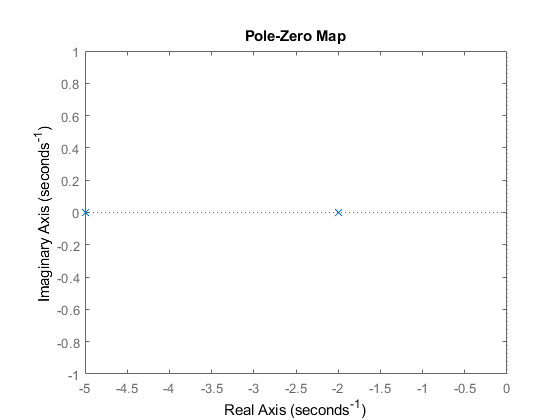

N1=[0 15];
D1=poly([-2 -5]) ; %calculates the coefficient of the polynomial when roots are given
figure
pzmap(tf(N1,D1))

Plot the natural and step response of $$G_{1}(s)$

syms s
R1=1/s; %step input
G1=15/((s+2)*(s+5));
C1=R1*G1 % step response

$$C1 = \frac{15}{s\,\left(s+2\right)\,\left(s+5\right)}$$

c1=ilaplace(C1)

$$c1 = {\mathrm{e}}^{-5\,t}-\frac{5\,{\mathrm{e}}^{-2\,t}}{2}+\frac{3}{2}$$

n1=c1-3/2 %natural response

$$n1 = {\mathrm{e}}^{-5\,t}-\frac{5\,{\mathrm{e}}^{-2\,t}}{2}$$

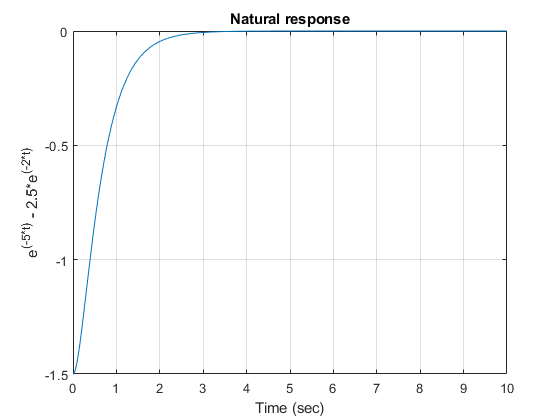

figure
fplot(n1,[0 10])
title('Natural response')
xlabel('Time (sec)')
ylabel('e^{(-5*t)} - 2.5*e^{(-2*t)}')
grid on

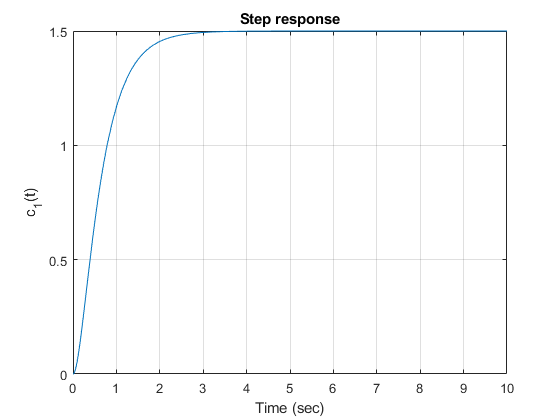

figure
fplot(c1,[0 10])
title('Step response')
xlabel('Time (sec)')
ylabel('c_{1}(t)')
grid on

 Consider the following second order system $$G_{2}(s)$ 


$$$G_{2}\left(s\right)=\frac{8}{\left(s^2+4s+8\right)}$$$


Pole zero plot of $$G_{2}(s)$

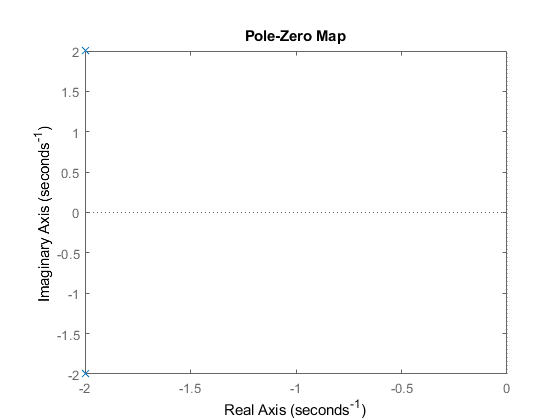

N2=[0 8];
D2=[1 4 8];
figure
pzmap(tf(N2,D2))

Plot the natural and step response of $$G_{2}(s)$

syms s
R2=1/s; % step input
G2=8/(s^2+4*s+8)

$$G2 = \frac{8}{s^{2}+4\,s+8}$$

C2=R2*G2 % step response

$$C2 = \frac{8}{s\,\left(s^{2}+4\,s+8\right)}$$

c2=ilaplace(C2)

$$c2 = 1-{\mathrm{e}}^{-2\,t}\,\left(\cos\left(2\,t\right)+\sin\left(2\,t\right)\right)$$

n2=c2-1 % natural response

$$n2 = -{\mathrm{e}}^{-2\,t}\,\left(\cos\left(2\,t\right)+\sin\left(2\,t\right)\right)$$

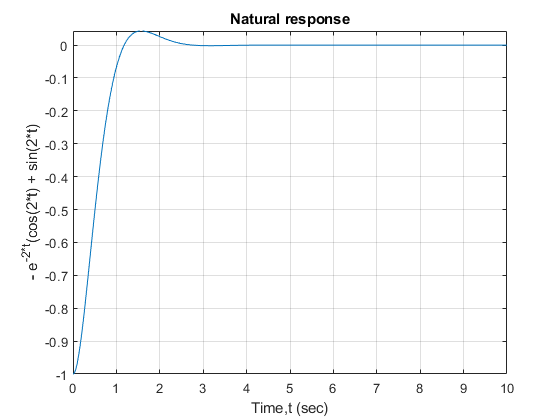

figure
fplot(n2, [0 10])
title('Natural response')
xlabel('Time,t (sec)')
ylabel('- e^{-2*t}(cos(2*t) + sin(2*t)')
grid on

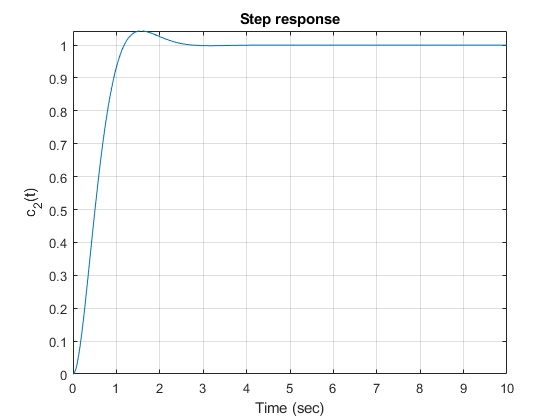

figure
fplot(c2,[0 10])
title('Step response')
xlabel('Time (sec)')
ylabel('c_{2}(t)')
grid on

Plot the step response of $$G_{1}(s)$ and $$G_{2}(s)$ in same figure

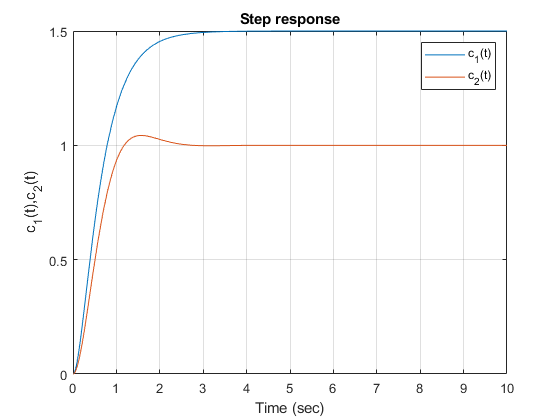

figure
fplot(c1,[0 10])
title('Step response')
xlabel('Time (sec)')
ylabel('c_{1}(t),c_{2}(t)')
grid on
hold on
fplot(c2,[0 10])
legend('c_{1}(t)','c_{2}(t)')
hold off

## Unstable system

A linear, time-invariant system is  ***unstable*** if the natural response grows without bound as time approaches infinity.


$$$G_{3}\left(s\right)=\frac{15}{\left(s-2\right)\left(s-5\right)}$$$


Pole zero plot of $$G_{3}(s)$

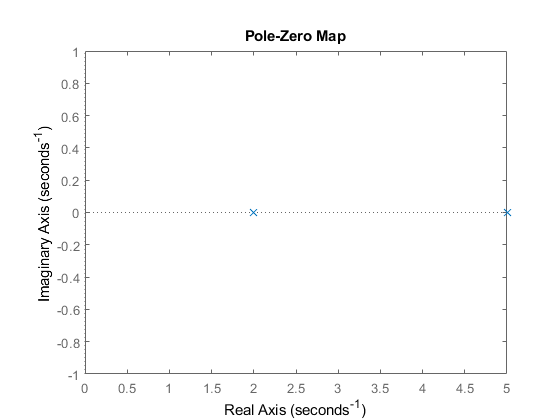

N3=[0 15];
D3=poly([2 5]) ;
figure
pzmap(tf(N3,D3))

Plot the natural and step response of $$G_{3}(s)$

syms s
R3=1/s; % step input
G3=15/((s-2)*(s-5))

$$G3 = \frac{15}{\left(s-2\right)\,\left(s-5\right)}$$

C3=R3*G3 % step response

$$C3 = \frac{15}{s\,\left(s-2\right)\,\left(s-5\right)}$$

c3=ilaplace(C3)

$$c3 = {\mathrm{e}}^{5\,t}-\frac{5\,{\mathrm{e}}^{2\,t}}{2}+\frac{3}{2}$$

n3=c3-1.5 % natural response

$$n3 = {\mathrm{e}}^{5\,t}-\frac{5\,{\mathrm{e}}^{2\,t}}{2}$$

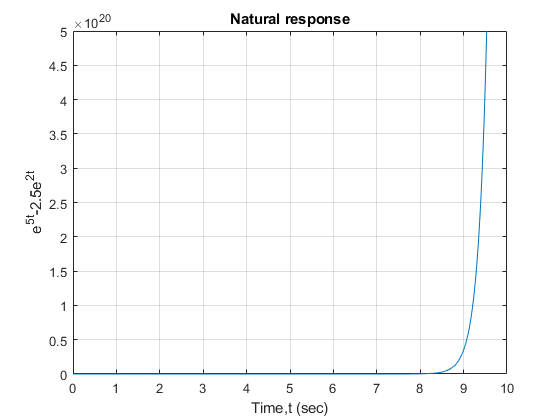

figure
fplot(n3, [0 10])
title('Natural response')
xlabel('Time,t (sec)')
ylabel('e^{5t}-2.5e^{2t}')
grid on

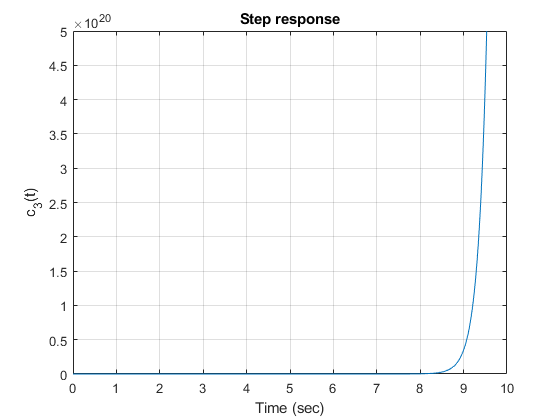

figure
fplot(c3,[0 10])
title('Step response')
xlabel('Time (sec)')
ylabel('c_{3}(t)')
grid on


$$$G_{4}\left(s\right)=\frac{8}{\left(s^2-4s+8\right)}$$$


Pole zero plot of $$G_{4}(s)$

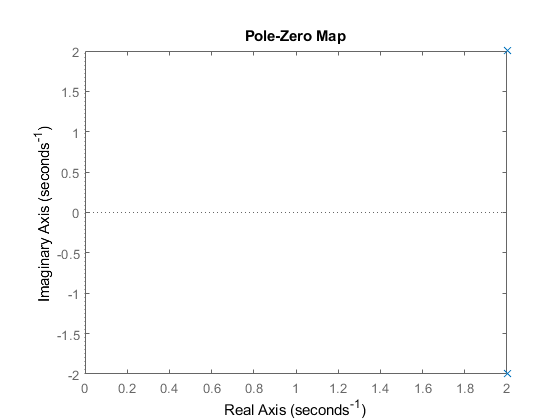

N4=[0 8];
D4=[1 -4 8];
figure
pzmap(tf(N4,D4))

Plot the natural and step response of $$G_{4}(s)$

syms s
R4=1/s; %step input
G4=8/(s^2-4*s+8)

$$G4 = \frac{8}{s^{2}-4\,s+8}$$

C4=R4*G4

$$C4 = \frac{8}{s\,\left(s^{2}-4\,s+8\right)}$$

c4=ilaplace(C4)

$$c4 = 1-{\mathrm{e}}^{2\,t}\,\left(\cos\left(2\,t\right)-\sin\left(2\,t\right)\right)$$

n4=c4-1% natural response

$$n4 = -{\mathrm{e}}^{2\,t}\,\left(\cos\left(2\,t\right)-\sin\left(2\,t\right)\right)$$

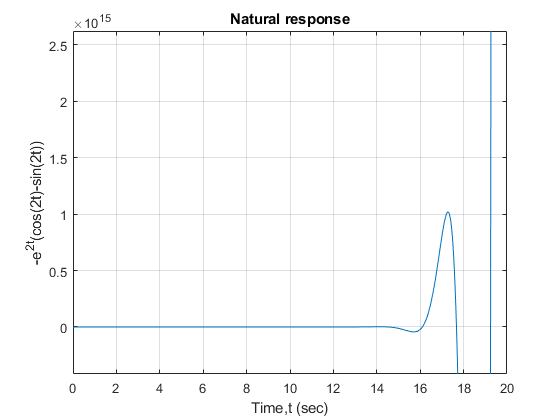

figure
fplot(n4, [0 20])
title('Natural response')
xlabel('Time,t (sec)')
ylabel('-e^{2t}(cos(2t)-sin(2t))')
grid on

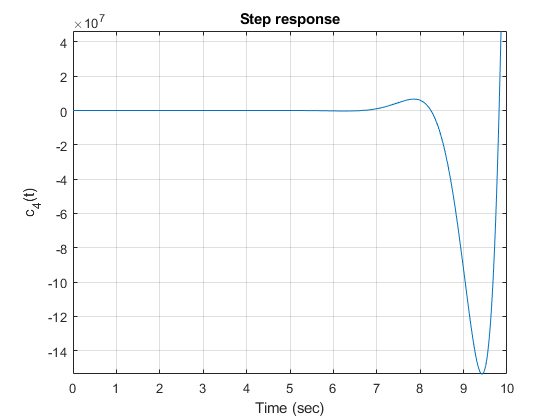

figure
fplot(c4,[0 10 ])
title('Step response')
xlabel('Time (sec)')
ylabel('c_{4}(t)')
grid on

Plot the step response of $$G_{3}(s)$ and $$G_{4}(s)$ in same figure

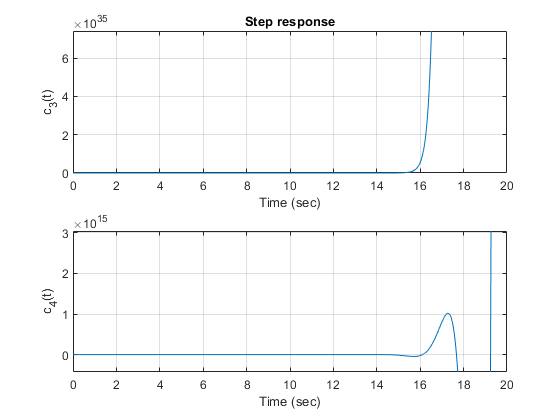

figure
subplot(2,1,1)
fplot(c3,[0 20])
title('Step response')
xlabel('Time (sec)')
ylabel('c_{3}(t)')
grid on
subplot(2,1,2)
fplot(c4,[0 20])
xlabel('Time (sec)')
ylabel('c_{4}(t)')
grid on

## Marginally stable system

A linear, time-invariant system is *marginally stable *if the natural response neither decays nor grows but remains constant or oscillate as time approaches infinity.


$$$G_{5}\left(s\right)=\frac{9}{\left(s^2+9\right)}$$$


Pole zero plot of $$G_{5}(s)$

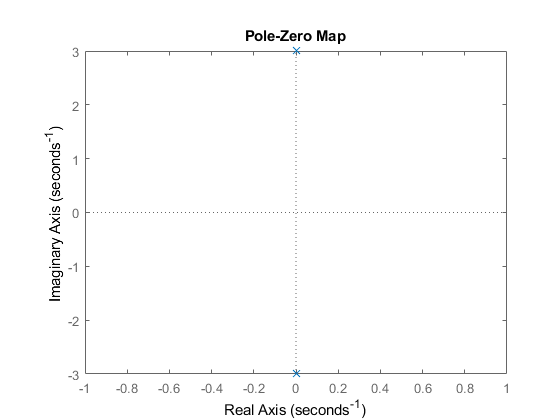

N5=[0 9];
D5=[1 0 9] ;
figure
pzmap(tf(N5,D5))

Plot the natural and step response of $$G_{5}(s)$

syms s
R5=1/s; %step input
G5=9/(s^2+9)

$$G5 = \frac{9}{s^{2}+9}$$

C5=R5*G5

$$C5 = \frac{9}{s\,\left(s^{2}+9\right)}$$

c5=ilaplace(C5)

$$c5 = 1-\cos\left(3\,t\right)$$

n5=c5-1% natural response

$$n5 = -\cos\left(3\,t\right)$$

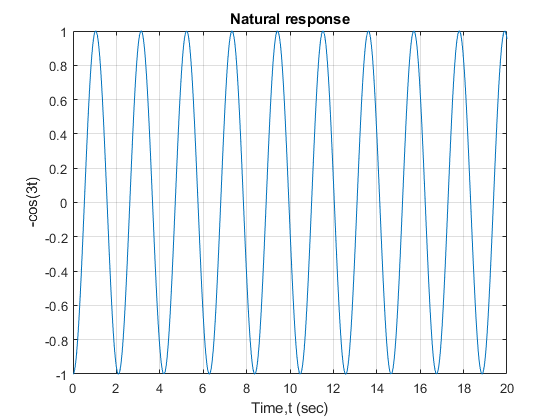

figure
fplot(n5, [0 20])
title('Natural response')
xlabel('Time,t (sec)')
ylabel('-cos(3t)')
grid on

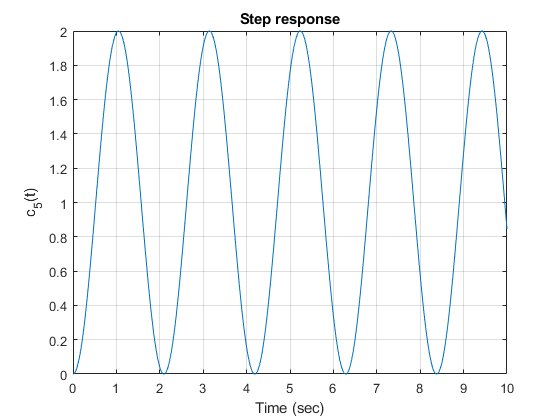

figure
fplot(c5,[0 10 ])
title('Step response')
xlabel('Time (sec)')
ylabel('c_{5}(t)')
grid on

## Special case unstable system

Repeated imaginary poles


$$$G_{6}\left(s\right)=\frac{81}{\left(s^2+9\right)^2}$$$


Pole zero plot of $$G_{6
}(s)$

N6=[0 81];
D6=[1 0 18 0 81]

D6 =      1     0    18     0    81


roots(D6)

ans =   -0.0000 + 3.0000i
  -0.0000 - 3.0000i
   0.0000 + 3.0000i
   0.0000 - 3.0000i


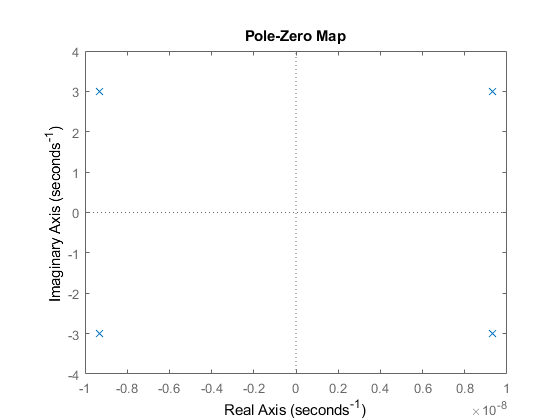

figure
pzmap(tf(N6,D6))

Plot the natural and step response of $$G_{6}(s)$

syms s
R6=1/s; %step input
G6=81/((s^2+9)^2)

$$G6 = \frac{81}{{\left(s^{2}+9\right)}^{2}}$$

C6=R6*G6

$$C6 = \frac{81}{s\,{\left(s^{2}+9\right)}^{2}}$$

c6=ilaplace(C6)

$$c6 = 1-\frac{3\,t\,\sin\left(3\,t\right)}{2}-\cos\left(3\,t\right)$$

n6=c6-1% natural response

$$n6 = -\cos\left(3\,t\right)-\frac{3\,t\,\sin\left(3\,t\right)}{2}$$

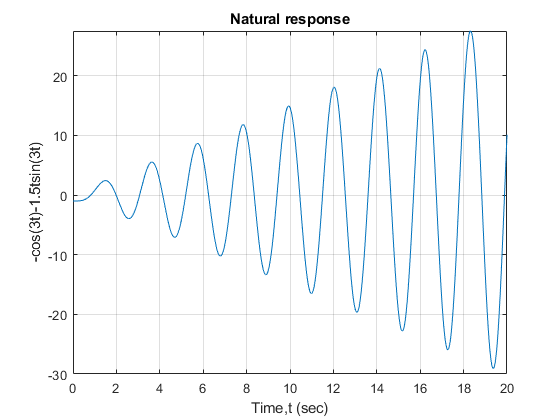

figure
fplot(n6, [0 20])
title('Natural response')
xlabel('Time,t (sec)')
ylabel('-cos(3t)-1.5tsin(3t)')
grid on

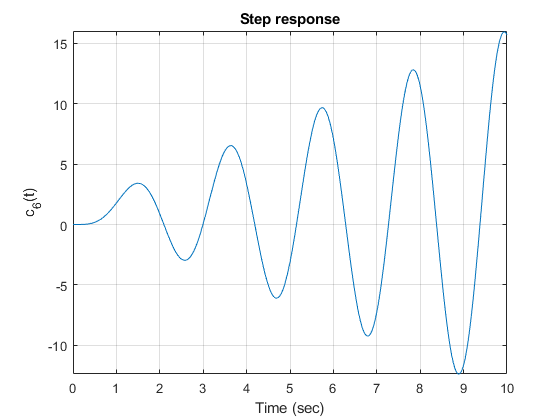

figure
fplot(c6,[0 10 ])
title('Step response')
xlabel('Time (sec)')
ylabel('c_{6}(t)')
grid on

## Closed loop stability of the system

### System 1

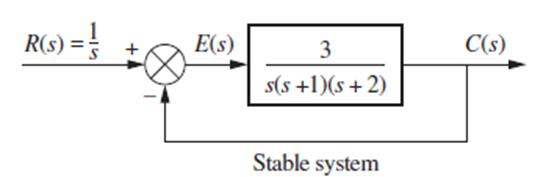

The closed loop transfer function of the above system will be:


$$$G_{7}(s)=\frac{C(s)}{R(s)}=\frac{3}{(s(s+1)(s+2)+3)}$$$


Pole zero plot of $$G_{7
}(s)$

N7=[0 3];
D7=[1 3 2 3]

D7 =      1     3     2     3


roots(D7)

ans =   -2.6717 + 0.0000i
  -0.1642 + 1.0469i
  -0.1642 - 1.0469i


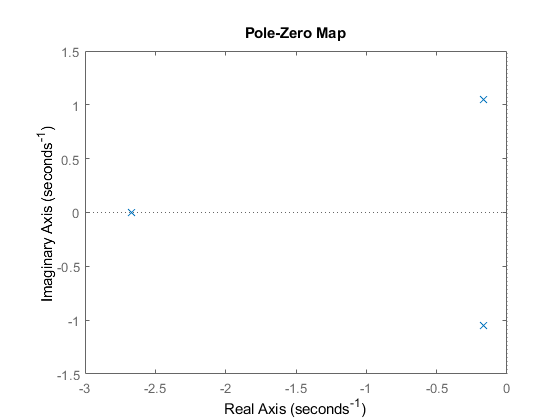

figure
pzmap(tf(N7,D7))

Plot the natural and step response of $$G_{7}(s)$

syms s
R7=1/s; %step input
G7=3/((s*(s+1)*(s+2))+3)

$$G7 = \frac{3}{s\,\left(s+1\right)\,\left(s+2\right)+3}$$

C7=R7*G7

$$C7 = \frac{3}{s\,\left(s\,\left(s+1\right)\,\left(s+2\right)+3\right)}$$

c7=ilaplace(C7)

$$c7 = \begin{array}{l} 1-2\,\left(\sum_{k=1}^{3}\frac{{\mathrm{e}}^{t\,\sigma_{1}}}{3\,{\sigma_{1}}^{2}+6\,\sigma_{1}+2}\right)-3\,\left(\sum_{k=1}^{3}\frac{{\mathrm{e}}^{\sigma_{1}\,t}\,\sigma_{1}}{6\,\sigma_{1}+3\,{\sigma_{1}}^{2}+2}\right)-\left(\sum_{k=1}^{3}\frac{{\mathrm{e}}^{t\,\sigma_{1}}\,{\sigma_{1}}^{2}}{3\,{\sigma_{1}}^{2}+6\,\sigma_{1}+2}\right)\\ \mathrm{where}\\ \sigma_{1}=\mathrm{root}\left({s_{3}}^{3}+3\,{s_{3}}^{2}+2\,s_{3}+3,s_{3},k\right) \end{array}$$

n7=c7-1% natural response

$$n7 = \begin{array}{l} -\left(\sum_{k=1}^{3}\frac{{\mathrm{e}}^{t\,\sigma_{1}}\,{\sigma_{1}}^{2}}{3\,{\sigma_{1}}^{2}+6\,\sigma_{1}+2}\right)-2\,\left(\sum_{k=1}^{3}\frac{{\mathrm{e}}^{t\,\sigma_{1}}}{3\,{\sigma_{1}}^{2}+6\,\sigma_{1}+2}\right)-3\,\left(\sum_{k=1}^{3}\frac{{\mathrm{e}}^{\sigma_{1}\,t}\,\sigma_{1}}{6\,\sigma_{1}+3\,{\sigma_{1}}^{2}+2}\right)\\ \mathrm{where}\\ \sigma_{1}=\mathrm{root}\left({s_{3}}^{3}+3\,{s_{3}}^{2}+2\,s_{3}+3,s_{3},k\right) \end{array}$$

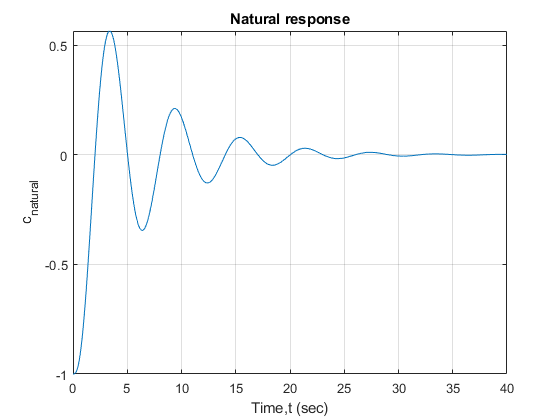

figure
fplot(n7, [0 40])
title('Natural response')
xlabel('Time,t (sec)')
ylabel('c_{natural}')
grid on

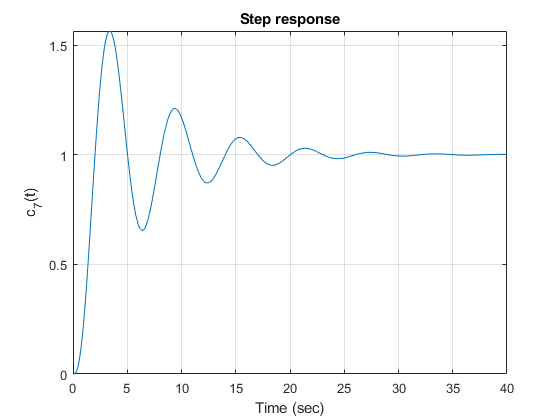

figure
fplot(c7,[0 40])
title('Step response')
xlabel('Time (sec)')
ylabel('c_{7}(t)')
grid on

### System 2

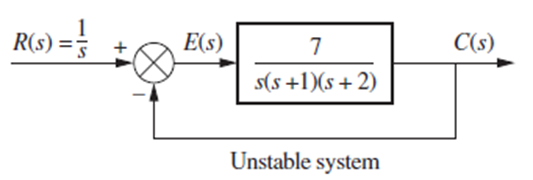

The closed loop transfer function of the above system will be:


$$$G_{8}(s)=\frac{C(s)}{R(s)}=\frac{7}{(s(s+1)(s+2)+7)}$$$


Pole zero plot of $$G_{8
}(s)$

N8=[0 7];
D8=[1 3 2 7]

D8 =      1     3     2     7


roots(D8)

ans =   -3.0867 + 0.0000i
   0.0434 + 1.5053i
   0.0434 - 1.5053i


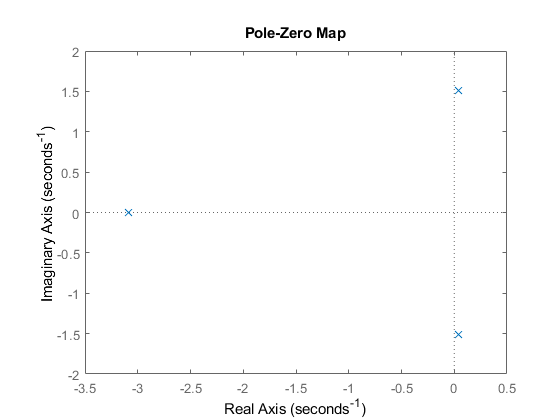

figure
pzmap(tf(N8,D8))

Plot the natural and step response of $$G_{8}(s)$

syms s
R8=1/s; %step input
G8=7/((s*(s+1)*(s+2))+7)

$$G8 = \frac{7}{s\,\left(s+1\right)\,\left(s+2\right)+7}$$

C8=R8*G8

$$C8 = \frac{7}{s\,\left(s\,\left(s+1\right)\,\left(s+2\right)+7\right)}$$

c8=ilaplace(C8)

$$c8 = \begin{array}{l} 1-2\,\left(\sum_{k=1}^{3}\frac{{\mathrm{e}}^{t\,\sigma_{1}}}{3\,{\sigma_{1}}^{2}+6\,\sigma_{1}+2}\right)-3\,\left(\sum_{k=1}^{3}\frac{{\mathrm{e}}^{\sigma_{1}\,t}\,\sigma_{1}}{6\,\sigma_{1}+3\,{\sigma_{1}}^{2}+2}\right)-\left(\sum_{k=1}^{3}\frac{{\mathrm{e}}^{t\,\sigma_{1}}\,{\sigma_{1}}^{2}}{3\,{\sigma_{1}}^{2}+6\,\sigma_{1}+2}\right)\\ \mathrm{where}\\ \sigma_{1}=\mathrm{root}\left({s_{4}}^{3}+3\,{s_{4}}^{2}+2\,s_{4}+7,s_{4},k\right) \end{array}$$

n8=c8-1% natural response

$$n8 = \begin{array}{l} -\left(\sum_{k=1}^{3}\frac{{\mathrm{e}}^{t\,\sigma_{1}}\,{\sigma_{1}}^{2}}{3\,{\sigma_{1}}^{2}+6\,\sigma_{1}+2}\right)-2\,\left(\sum_{k=1}^{3}\frac{{\mathrm{e}}^{t\,\sigma_{1}}}{3\,{\sigma_{1}}^{2}+6\,\sigma_{1}+2}\right)-3\,\left(\sum_{k=1}^{3}\frac{{\mathrm{e}}^{\sigma_{1}\,t}\,\sigma_{1}}{6\,\sigma_{1}+3\,{\sigma_{1}}^{2}+2}\right)\\ \mathrm{where}\\ \sigma_{1}=\mathrm{root}\left({s_{4}}^{3}+3\,{s_{4}}^{2}+2\,s_{4}+7,s_{4},k\right) \end{array}$$

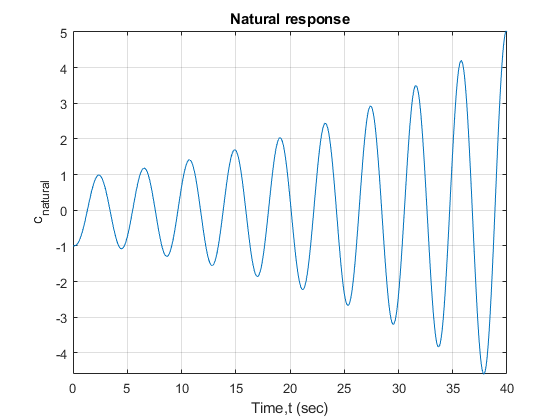

figure
fplot(n8, [0 40])
title('Natural response')
xlabel('Time,t (sec)')
ylabel('c_{natural}')
grid on

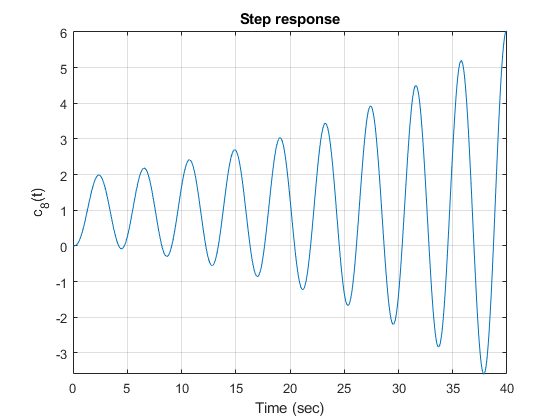

figure
fplot(c8,[0 40])
title('Step response')
xlabel('Time (sec)')
ylabel('c_{8}(t)')
grid on

## References

[1]     Nise, Norman S.,* Control Systems Engineering, *7th ed, Hoboken, NJ:Wiley, 2004.

[2]     K. Webb, Class Lecture, Topic: "Section 6: Stability" ESE499, College of Engineering, OSU-Cascades, Oregon,* accesed on*:June 2s